# Hypothesis Testing

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Hypothesis Testing')

## 1 Sample t-test (Example 1 cont'd)

t0 = (-0.61 - 0)/(1.62/(12)^(1/2))

t0 = -1.3044

alpha = 0.05;
tcrit0 = icdf('t', alpha, 12 - 1) % (alpha, df) - NOTICE alpha!

tcrit0 = -1.7959

pval0 = tcdf(t0,12 - 1) % looking at LEFT tail

pval0 = 0.1094

## 1 Sample t-test (Example 2 cont'd)

t0 = (146-140)/(27/(157)^(1/2))

t0 = 2.7844

alpha = 0.05;
tcrit0 = icdf('t', 1 - alpha, 157 - 1) % (1-alpha, n - 1) - NOTICE 1-alpha!

tcrit0 = 1.6547

pval0 = 1 - tcdf(t0,157 - 1) % looking at RIGHT tail (1 - p)!

pval0 = 0.0030

n1 = 157

n1 = 157

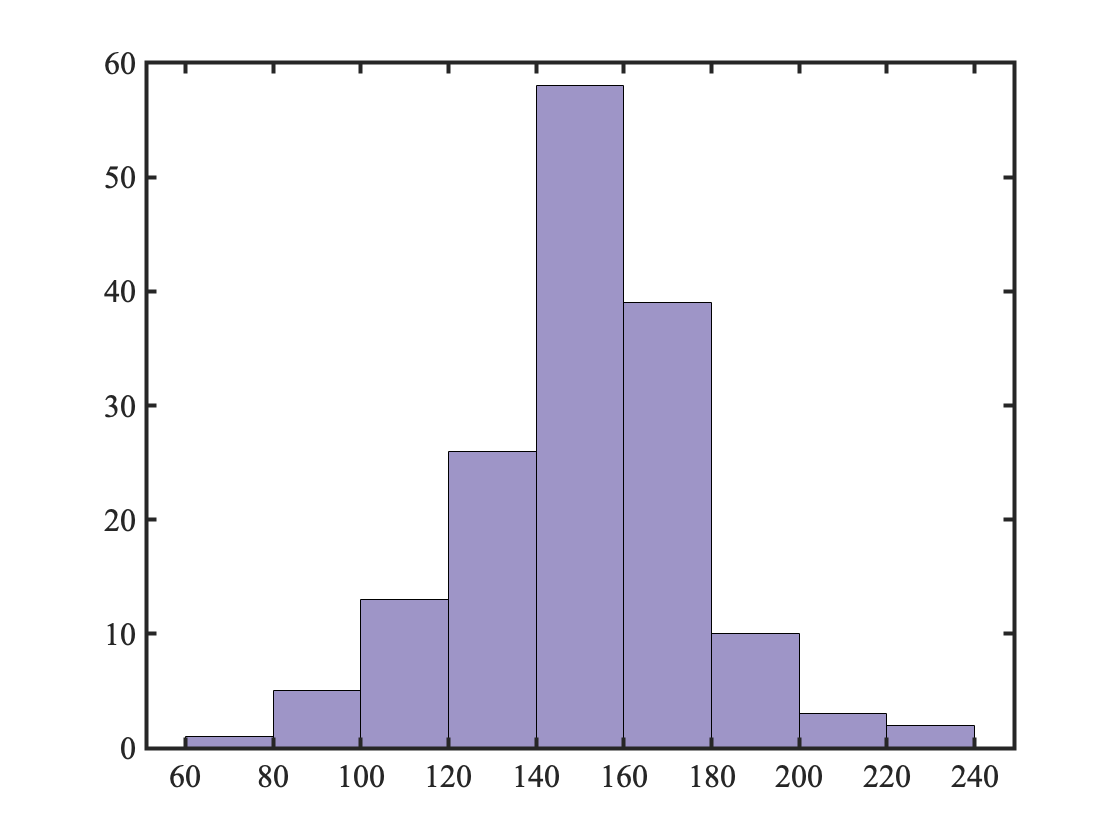

alpha1 = 0.05;
data1 = normrnd(146, 27, [n1 1]);
figure();
histogram(data1)
auto_save('example2hist')


t1 = (mean(data1) - 140) / (std(data1) / (157)^(1/2))

t1 = 5.2446

tcrit1 = icdf('t', 1 - alpha1, n1 - 1)

tcrit1 = 1.6547

pval1 = 1 - tcdf(t1,n1 - 1)

pval1 = 2.5145e-07


[h,p,ci,stats] = ttest(data1, 140, 'tail', 'right')

h = 1

p = 2.5145e-07

ci =   147.6131
       Inf


stats = struct with fields:
    tstat: 5.2446
       df: 156
       sd: 26.5724

## 1 Sample t-test (Example 3 cont'd)

data2 = [13,14,15,17,18,19,21,20,19,20];
alpha = 0.05;
t2 = (mean(data2) - 15) / (std(data2) / (length(data2))^(1/2));
tcrit2 = icdf('t', alpha/2, length(data2)-1); % Left tail (alpha/2 = 0.025)
pval2 = 2*tcdf(-abs(t2),length(data2) - 1); % -abs() do calc on left-tail
% multiply by 2 (accounting for both sided)
abs(t2)

ans = 2.9824

abs(tcrit2)

ans = 2.2622

pval2

pval2 = 0.0154


[h,p,ci,stats] = ttest(data2, 15, 'tail', "both")

h = 1

p = 0.0154

ci =    15.6279   19.5721


stats = struct with fields:
    tstat: 2.9824
       df: 9
       sd: 2.7568

## 2 Sample Welch's t-test (Example 4 cont'd)

t4 = ((306.7 - 300.4)-(0-0))/(34.9^2 / 300 + 30.1^2 / 350)^(1/2);
v4 = (34.9^2 / 300 + 30.1^2 / 350)^2 / (34.9^4 / (300^2 * (300 - 1)) + 30.1^4 / (350^2 * (350-1)));
alpha4 = 0.01;
tcrit4 = icdf('t', alpha4/2, v4);
pval4 = 2*tcdf(-abs(t4),v4);
abs(t4)

ans = 2.4433

abs(tcrit4)

ans = 2.5841

pval4

pval4 = 0.0148


group1 = normrnd(300.4, 34.9, [300 1]);
group2 = normrnd(306.7, 30.1, [350 1]);
[h,p,ci,stats] = ttest2(group1, group2, "Tail","both")

h = 1

p = 1.9945e-04

ci =   -14.5222
   -4.5248


stats = struct with fields:
    tstat: -3.7411
       df: 648
       sd: 32.3545

## Paired t-test (Example 5 cont'd)

data5a = [22,25,17,24,16,29,20,23,19,20];
data5b = [18,21,16,22,19,24,17,21,23,18];
data5diff = data5a - data5b;
t5 = (mean(data5diff) - 0) / (std(data5diff) / (length(data5diff))^(1/2));
tcrit5 = icdf('t', 0.05/2, length(data5diff)-1);
pval5 = 2*tcdf(-abs(t5),length(data5diff)-1);
abs(t5)

ans = 1.7143

abs(tcrit5)

ans = 2.2622

pval5

pval5 = 0.1206


[h,p,ci,stats] = ttest(data5a, data5b, "Tail","both")

h = 0

p = 0.1206

ci =    -0.5113    3.7113


stats = struct with fields:
    tstat: 1.7143
       df: 9
       sd: 2.9515

## Mann-Whitney U Example

G1 = [4,7,8,9,13,13,17,11];
G2 = [23,6,3,24,17,14,24,29,13,33];
[p,h,stats] = ranksum(G1,G2, 'method', "approximate")

p = 0.0612

h = logical
   0

stats = struct with fields:
       zval: -1.8717
    ranksum: 54.5000

## Wilcoxon signed-rank Example

alpha = 0.05;
Nr = 9;
W = abs(1.5 + 1.5 - 3 - 4 - 5 - 6 + 7 + 8 + 9);
% calculate Wcrit (instead of lookup table)
% 0.05/2 = 2-tailed; 0.05 = 1 tailed
% Wcrit = -(qsignrank(alpha/2, Nr, lower.tail=FALSE)+1)+Nr*(Nr+1)/2
G1 = [125,115,130,140,140,115,140,125,140,135];
G2 = [110,122,125,120,140,124,123,137,135,145];
[p,h,stats] = signrank(G1,G2)

p = 0.6328

h = logical
   0

stats = struct with fields:
    signedrank: 27

## Bonferroni

pvals = [0.01 0.02 0.04]; % NOTICE: already sorted 
adjusted = pvals .* repelem(length(pvals), length(pvals))

adjusted =     0.0300    0.0600    0.1200


## Holm-Bonferroni

pvals = [0.01 0.02 0.04]; % NOTICE: already sorted 
adjusted = pvals .* [length(pvals):-1:1] % all significant, so all corrected

adjusted =     0.0300    0.0400    0.0400
